clc;
clear;
syms Pb(t) Pw(t) T(t)

ode1 = diff(Pb) == -T;
ode2 = diff(Pw) == T;
ode3 = diff(T) == 4*(Pb-Pw);
odes = [ode1;ode2;ode3];
cond1 = Pb(0) == 10;
cond2 = Pw(0) == 10;
cond3 = T(0) == -1;
conds = [cond1; cond2; cond3];
[PbSol(t), PwSol(t), TSol(t)] = dsolve(odes,conds)

$$PbSol(t) = \frac{\sqrt{8}\,\sin\left(\sqrt{8}\,t\right)}{8}+10$$

$$PwSol(t) = 10-\frac{\sqrt{8}\,\sin\left(\sqrt{8}\,t\right)}{8}$$

$$TSol(t) = -\cos\left(\sqrt{8}\,t\right)$$

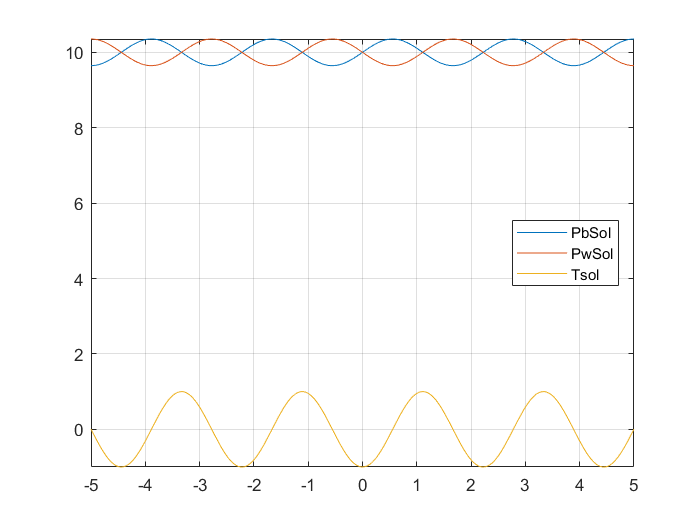

fplot(PbSol)
hold on
fplot(PwSol)
hold on
fplot(TSol)
grid on
legend('PbSol','PwSol','Tsol','Location','best')

hold off

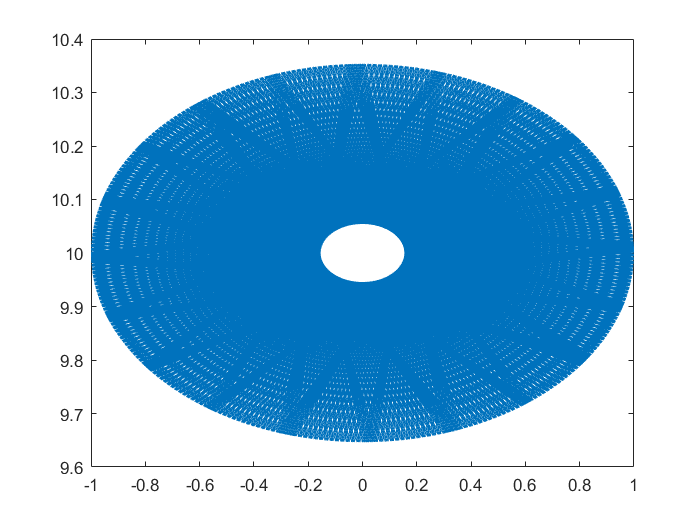

tt= 1:1000;
plot(-TSol(tt),PbSol(tt))